x_max = 55;
N_max_gr = 8;
gamma0 = 0;
gamma1 = 1;
gamma2 = 3;

x_eff = 11.8;
x_eff_real = 16;
psi = 0.96;
psi_real = 1.008;
A = [1.0075 1.0095 1.01]';
A_real = [1.0018 1.016 1.009]';
% I'm not going to bother writing out the group number bit since it will
% cancel with the 10
B = [1.65 2.07 2.47]';
B_real = [1.6969 2.2175 1.6709]';
lambda = 700;

x_con_init = [20 22 25 27 17]; 
x_aux_init = [6 6 7 7 8];

parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

parameters_pred = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff, ...
    'psi', psi, ...
    'A', A, ...
    'B', B, ...
    'lambda', lambda);


Np = 10;
parameters = parameters_real;

xk = [55;8];
[a,b,c] = functionForAll(Np, xk, parameters, 0)

a =      0
     0


b = 0

c = 0

## Real 2.5

run = true;
if run
    finduOpt = @(xk) functionForAll2(Np, xk, parameters_pred, -1);
    realUpdate = @(xk, uk) functionForAll2(Np, xk, parameters_real, uk);
    
    
    %[x_next, u_opt, J_opt] = realUpdate(xk, 0)
    
    T_end = 40; 
    
    xk = zeros(2,5, T_end + 1); % xcon/xaux, section, time
    u_k = zeros(5,T_end+1)
    xk(:, :, 1) = [x_con_init ; x_aux_init]; % Set initial conditions
    total_cost = 0;
    tic
    for i = 2:T_end+1
        disp("x_k = " + num2str(xk(:,:,i-1)))
        disp("time_elapsed = " + num2str(toc) + "seconds")
        disp("time step " + num2str(i-1) + " of " + num2str(T_end))
        for j = 1:5
            [~,u_k(j,i), ~] = finduOpt(xk(:,j,i-1)); 
            [xk(:,j,i), ~, J] = realUpdate(xk(:,j,i-1), u_k(j,i));
            total_cost = total_cost + J;
        end
    end
end

u_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0

    "x_k = 20  22  25  27  17"
    "x_k =  6   6   7   7   8"



time_elapsed = 0.00257seconds


time step 1 of 40


    "x_k = 21.7329      23.7365      26.7419      28.7455      18.7275"
    "x_k =       6            6            7            7            8"



time_elapsed = 0.97245seconds


time step 2 of 40


    "x_k = 23.4689      25.4761      28.4869      30.4941      20.4581"
    "x_k =       6            6            7            7            8"



time_elapsed = 1.9394seconds


time step 3 of 40


    "x_k = 25.2081      27.2189      30.2351      14.6101      22.1918"
    "x_k =       6            6            7            8            8"



time_elapsed = 2.9488seconds


time step 4 of 40


    "x_k = 26.9503      28.9648       14.349      16.3333      23.9287"
    "x_k =       6            6            8            8            8"



time_elapsed = 4.0265seconds


time step 5 of 40


    "x_k = 28.6957      30.7138      16.0717      18.0596      25.6687"
    "x_k =       6            6            8            8            8"



time_elapsed = 4.6125seconds


time step 6 of 40


    "x_k = 30.4443      14.8315      17.7976       19.789      27.4118"
    "x_k =       6            7            8            8            8"



time_elapsed = 5.7192seconds


time step 7 of 40


    "x_k = 14.5599      16.5551      19.5265      21.5215       29.158"
    "x_k =       7            7            8            8            8"



time_elapsed = 6.4676seconds


time step 8 of 40


    "x_k = 16.283      18.2818      21.2585      23.2572      30.9074"
    "x_k =      7            7            8            8            8"



time_elapsed = 7.1782seconds


time step 9 of 40


    "x_k = 18.0092      20.0116      22.9937      24.9959            0"
    "x_k =       7            7            8            8            0"



time_elapsed = 7.875seconds


time step 10 of 40


    "x_k = 19.7385      21.7445       24.732      26.7378       1.6969"
    "x_k =       7            7            8            8            0"



time_elapsed = 8.5878seconds


time step 11 of 40


    "x_k = 21.4709      23.4806      26.4734      28.4828      3.39685"
    "x_k =       7            7            8            8            0"



time_elapsed = 9.1596seconds


time step 12 of 40


    "x_k = 23.2065      25.2198       28.218       30.231      5.09987"
    "x_k =       7            7            8            8            0"



time_elapsed = 9.8004seconds


time step 13 of 40


    "x_k = 24.9451       26.962      29.9656            0      6.80595"
    "x_k =       7            7            8            0            0"



time_elapsed = 10.45seconds


time step 14 of 40


    "x_k = 26.6869      28.7075      31.7165       1.6969       8.5151"
    "x_k =       7            7            8            0            0"



time_elapsed = 11.0032seconds


time step 15 of 40


    "x_k = 28.4319      30.4561            0      3.39685      10.2273"
    "x_k =       7            7            0            0            0"



time_elapsed = 11.6509seconds


time step 16 of 40


    "x_k = 30.18      14.5717       1.6969      5.09987      11.9426"
    "x_k =     7            8            0            0            0"



time_elapsed = 12.289seconds


time step 17 of 40


    "x_k = 14.2934      16.2948      3.39685      6.80595       13.661"
    "x_k =       8            8            0            0            0"



time_elapsed = 12.8484seconds


time step 18 of 40


    "x_k = 16.016      18.0211      5.09987       8.5151      15.3825"
    "x_k =      8            8            0            0            0"



time_elapsed = 13.2734seconds


time step 19 of 40


    "x_k = 17.7417      19.7504      6.80595      10.2273      17.1071"
    "x_k =       8            8            0            0            0"



time_elapsed = 13.7028seconds


time step 20 of 40


    "x_k = 19.4706      21.4829       8.5151      11.9426      18.8348"
    "x_k =       8            8            0            0            0"



time_elapsed = 14.1845seconds


time step 21 of 40


    "x_k = 21.2025      23.2184      10.2273       13.661      20.5656"
    "x_k =       8            8            0            0            0"



time_elapsed = 14.6592seconds


time step 22 of 40


    "x_k = 22.9376      24.9571      11.9426      15.3825      22.2995"
    "x_k =       8            8            0            0            0"



time_elapsed = 15.2529seconds


time step 23 of 40


    "x_k = 24.6758      26.6989       13.661      17.1071      24.0366"
    "x_k =       8            8            0            0            0"



time_elapsed = 15.8504seconds


time step 24 of 40


    "x_k = 26.4171      28.4439      15.3825      18.8348      25.7767"
    "x_k =       8            8            0            0            0"



time_elapsed = 16.5546seconds


time step 25 of 40


    "x_k = 28.1616       30.192      17.1071      20.5656        27.52"
    "x_k =       8            8            0            0            0"



time_elapsed = 16.8957seconds


time step 26 of 40


    "x_k = 29.9091            0      18.8348      22.2995      29.2665"
    "x_k =       8            0            0            0            0"



time_elapsed = 17.324seconds


time step 27 of 40


    "x_k = 31.6599       1.6969      20.5656      24.0366       31.016"
    "x_k =       8            0            0            0            0"



time_elapsed = 17.8604seconds


time step 28 of 40


    "x_k = 0      3.39685      22.2995      25.7767      15.1362"
    "x_k = 0            0            0            0            1"



time_elapsed = 18.5197seconds


time step 29 of 40


    "x_k = 1.6969      5.09987      24.0366        27.52      16.8603"
    "x_k =      0            0            0            0            1"



time_elapsed = 18.8394seconds


time step 30 of 40


    "x_k = 3.39685      6.80595      25.7767      29.2665      18.5876"
    "x_k =       0            0            0            0            1"



time_elapsed = 19.1941seconds


time step 31 of 40


    "x_k = 5.09987       8.5151        27.52       31.016      20.3179"
    "x_k =       0            0            0            0            1"



time_elapsed = 19.6428seconds


time step 32 of 40


    "x_k = 6.80595      10.2273      29.2665      15.1362      22.0514"
    "x_k =       0            0            0            1            1"



time_elapsed = 20.2034seconds


time step 33 of 40


    "x_k = 8.5151      11.9426       31.016      16.8603       23.788"
    "x_k =      0            0            0            1            1"



time_elapsed = 20.7082seconds


time step 34 of 40


    "x_k = 10.2273       13.661      15.1362      18.5876      25.5277"
    "x_k =       0            0            1            1            1"



time_elapsed = 21.3546seconds


time step 35 of 40


    "x_k = 11.9426      15.3825      16.8603      20.3179      27.2706"
    "x_k =       0            0            1            1            1"



time_elapsed = 21.8592seconds


time step 36 of 40


    "x_k = 13.661      17.1071      18.5876      22.0514      29.0165"
    "x_k =      0            0            1            1            1"



time_elapsed = 22.3434seconds


time step 37 of 40


    "x_k = 15.3825      18.8348      20.3179       23.788      30.7657"
    "x_k =       0            0            1            1            1"



time_elapsed = 22.9614seconds


time step 38 of 40


    "x_k = 17.1071      20.5656      22.0514      25.5277      14.8838"
    "x_k =       0            0            1            1            2"



time_elapsed = 23.527seconds


time step 39 of 40


    "x_k = 18.8348      22.2995       23.788      27.2706      16.6075"
    "x_k =       0            0            1            1            2"



time_elapsed = 23.9984seconds


time step 40 of 40


## chatgpt plotting

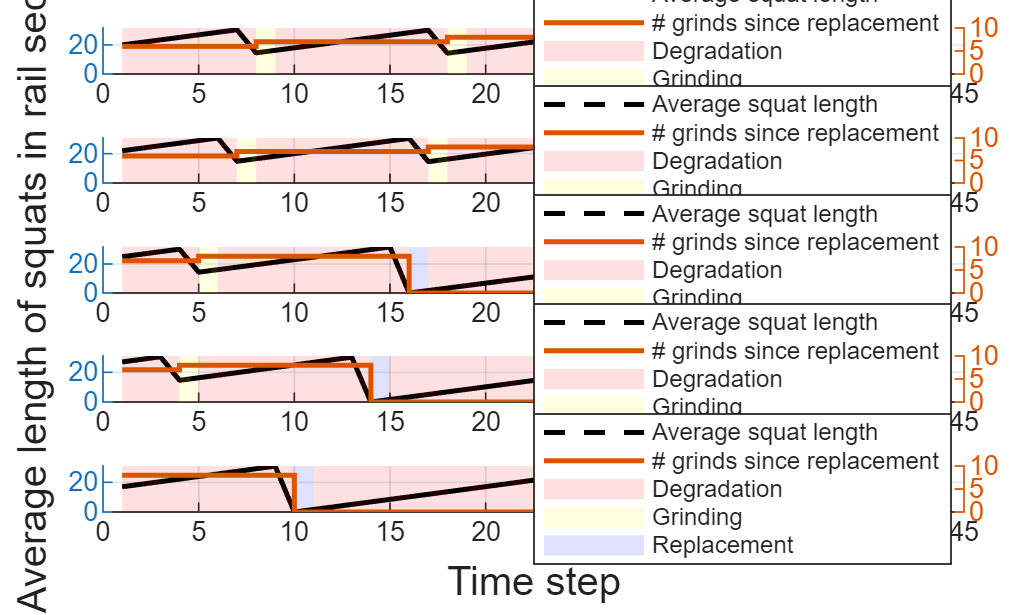

t = 1:T_end+1;

figure;
bigPlot = tiledlayout(5,1,'TileSpacing','compact','Padding','compact');

xlabel(bigPlot,'Time step')
ylabel(bigPlot,'Average length of squats in rail section')

for j = 1:5

    ax = nexttile;
    hold(ax,'on')
    grid(ax,'on')

    y_cont = squeeze(xk(1,j,:));
    y_disc = squeeze(xk(2,j,:));
    colour_state = squeeze(u_k(j,:));

    % ---------------------------
    % Continuous signal
    % ---------------------------
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    drawnow
    yl = ylim(ax);

    % ---------------------------
    % Background colour regions
    % ---------------------------
    for k = 1:length(t)-1

        switch colour_state(k)

            case 0
                c = [1 0 0]; % red

            case 1
                c = [1 1 0]; % yellow

            case 2
                c = [0 0 1]; % blue

            otherwise
                c = [0.8 0.8 0.8];
        end

        patch(ax,...
            [t(k) t(k+1) t(k+1) t(k)],...
            [yl(1) yl(1) yl(2) yl(2)],...
            c,...
            'FaceAlpha',0.12,...
            'EdgeColor','none',...
            'HandleVisibility','off');   % prevents legend duplication
    end

    % redraw line on top of patches
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    % ---------------------------
    % Discrete signal
    % ---------------------------
    yyaxis(ax,'right')
    h_disc = stairs(ax,t,y_disc,'LineWidth',1.5);

    % ---------------------------
    % Dummy objects for legend
    % ---------------------------
    h_red    = patch(nan,nan,[1 0 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_yellow = patch(nan,nan,[1 1 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_blue   = patch(nan,nan,[0 0 1],'FaceAlpha',0.12,'EdgeColor','none');

    % ---------------------------
    % Legend
    % ---------------------------
    legend(ax,...
        [h_cont h_disc h_red h_yellow h_blue],...
        {'Average squat length','# grinds since replacement',...
         'Degradation','Grinding','Replacement'},...
        'Location','best')

end

## Real 2.6

function totalCost = doMe(var)
    x_max = 38;
    N_max_gr = 8;
    gamma0 = 0;
    gamma1 = 1;
    gamma2 = 3;
    
    x_eff_real = 16;
    psi_real = 1.008;
    A_real = [1.0018 1.016 1.009]';
    B_real = [1.6969 2.2175 1.6709]';
    lambda = 700;

    parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

    N_gr = var(1); M = round(var(2));
    xk = [0;0];
    parameters_real.N_max_gr = N_gr;
    Np = 8;
    T_end = 20; 
    IDs = 1:M:T_end; u = zeros(1,T_end); u(IDs) = 1;
    totalCost = 0;
    for i = 1:T_end
        [xk,~,J] = functionForAll(Np, xk, parameters_real, u(i));
        totalCost = totalCost + J;
        if(xk(2) >= N_gr)
            u(i+1) = 2;
        end
    end 
end
tic
LB = [0,0]; UB = [19, 19];
doMeNow = @doMe;
N_M = ga(doMeNow, 2, zeros(1,2), 0, zeros(1,2) ,0, LB, UB); % took 25 minutes to run, game N_max = 0.54, M = 1.8339
N_max_gr = N_M(1);
M = N_M(2);
time = toc;




## testing

function [x, us, totalCost] = doMe2(var)
    x_max = 38;
    N_max_gr = 8;
    gamma0 = 0;
    gamma1 = 1;
    gamma2 = 3;
    
    x_eff_real = 16;
    psi_real = 1.008;
    A_real = [1.0018 1.016 1.009]';
    B_real = [1.6969 2.2175 1.6709]';
    lambda = 700;

    parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

    N_gr = var(1); M = round(var(2));
    xk = [0;0];
    parameters_real.N_max_gr = N_gr;
    Np = 1;
    T_end = 20; 
    IDs = 1:M:T_end; u = zeros(1,T_end); u(IDs) = 1;
    totalCost = 0;
    x = zeros(2,T_end);
    us = zeros(1,T_end);
    for i = 1:T_end
        [xk,u_current,J] = functionForAll(Np, xk, parameters_real, u(i));
        totalCost = totalCost + J;
        x(:,i) = xk; us(i) = u_current;
        if(xk(2) >= N_gr)
            u(i+1) = 2;
        end
    end 
end

[xs, us, J] = doMe2([19; 19])

N = size(xs,2);
tiledlayout(3,1)
nexttile
plot(1:N, xs(1,:));
nexttile
plot(1:N, xs(2,:));
nexttile
plot(1:N, us(:));